Parameters

fc = 2000; %2kHz
fs = 44.1e3;

Text Encoding

text = ['hello world, vicky was in the musical. ' ...
    'Yichen does not wear glasses' ...
    'Yichen smushed matlab' ...
    'turns out implementation is hard' ...
    'Vicky is happy she is a software engineering'...
    'Yichen is suprised by Vickys career choise'];

text_bin = dec2bin(double(text));
s = size(text_bin);
bin_str = reshape(text_bin.'-'0',1,[]);
% a = [];
% for c=1:length(bin_str)
%     append(a, str2double(bin_str(c)));
% end

Pulse Shaping

%pulse = (sqrt(2)*cos(2*pi*fc*time)).* bin_str;

Transmit

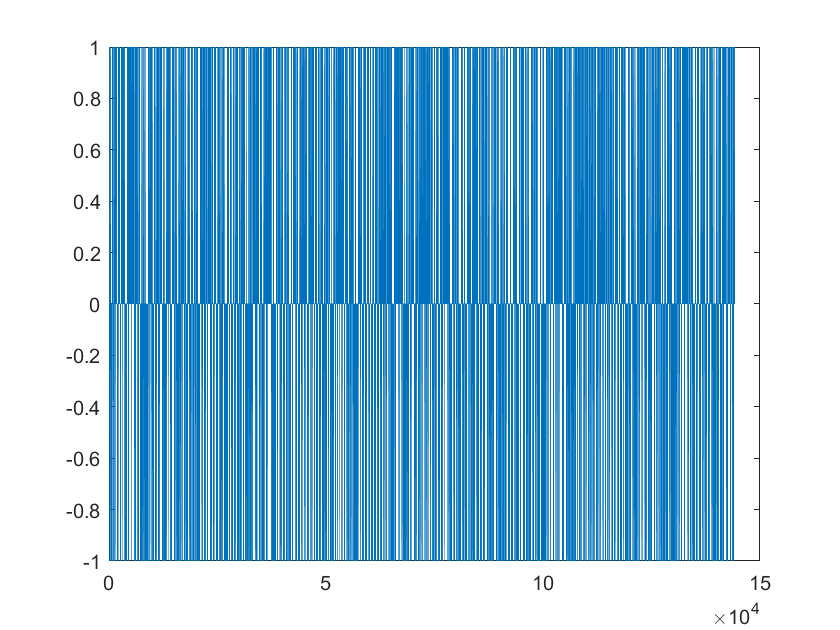

bin_str = 2 * bin_str - 1;
bin_str_us = upsample(bin_str, 100);
plot(bin_str_us);

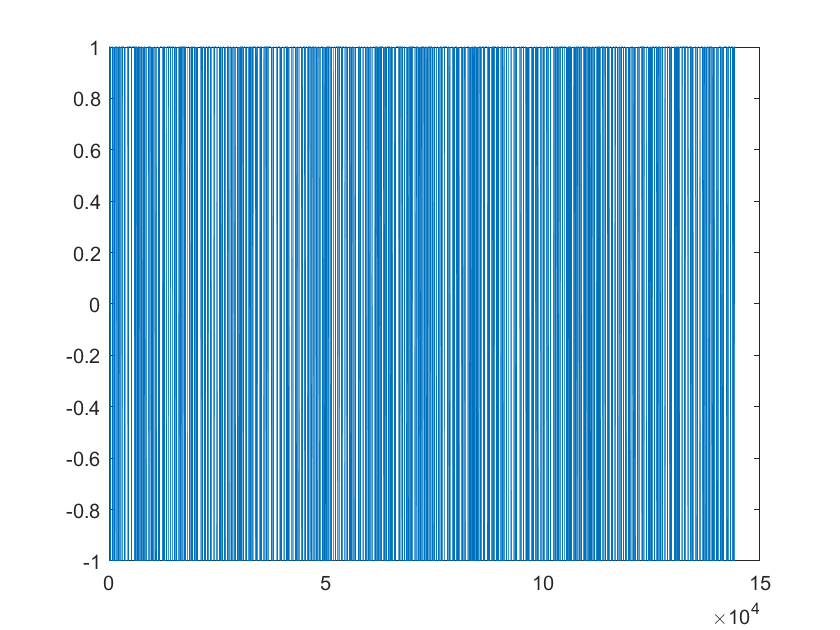

pulse = ones(100, 1);
X_I = conv(bin_str_us, pulse);
plot(X_I);

time = [0:length(X_I)-1]*1/fs;  %update to the length of the binary string
X = X_I .* cos(2*pi*fc*time) % then play this on the computer with sound

X =     1.0000    0.9597    0.8420    0.6563    0.4178    0.1455   -0.1385   -0.4113   -0.6509   -0.8381   -0.9576   -1.0000   -0.9617   -0.8458   -0.6617   -0.4242   -0.1526    0.1314    0.4048    0.6455    0.8342    0.9556    0.9999    0.9636    0.8496    0.6670    0.4307    0.1596   -0.1243   -0.3983   -0.6401   -0.8302   -0.9534   -0.9998   -0.9655   -0.8533   -0.6723   -0.4371   -0.1666    0.1173    0.3917    0.6346    0.8262    0.9513    0.9996    0.9673    0.8570    0.6776    0.4435    0.1736


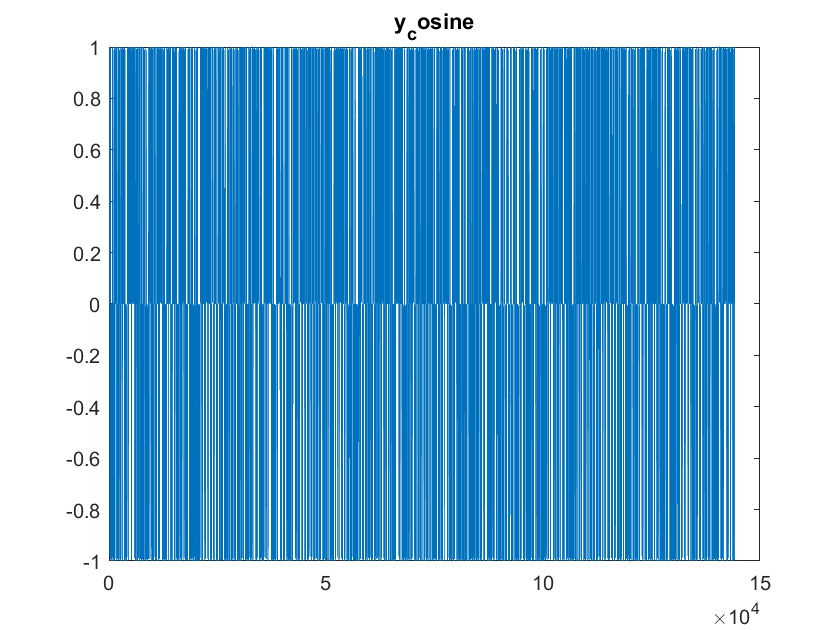

%n = randn(1000,1);
sound(X, fs, 8);


y_received = X;
% cosine and sine
fc = 2000;
fs = 44100;
time = [0:length(y_received)-1]*1/fs;
y_cos = y_received.*cos(2*pi*fc*time);
y_sin = - y_received.*sin(2*pi*fc*time)*1i;
figure();
plot(y_cos)
title('y_cosine')

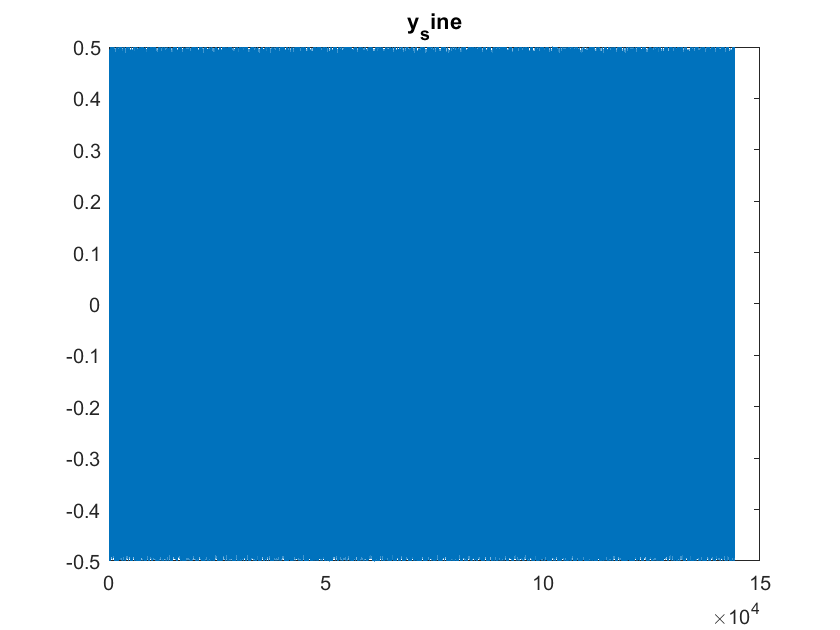

figure();
plot(imag(y_sin))
title('y_sine')

y_complex = y_cos + y_sin;
disp("lowpassing..");

lowpassing..


% we are not sure about the parameters for lowpass filter
y_complex = lowpass(y_complex, fc/10, 44.1e3);
disp("done lowpassing");

done lowpassing


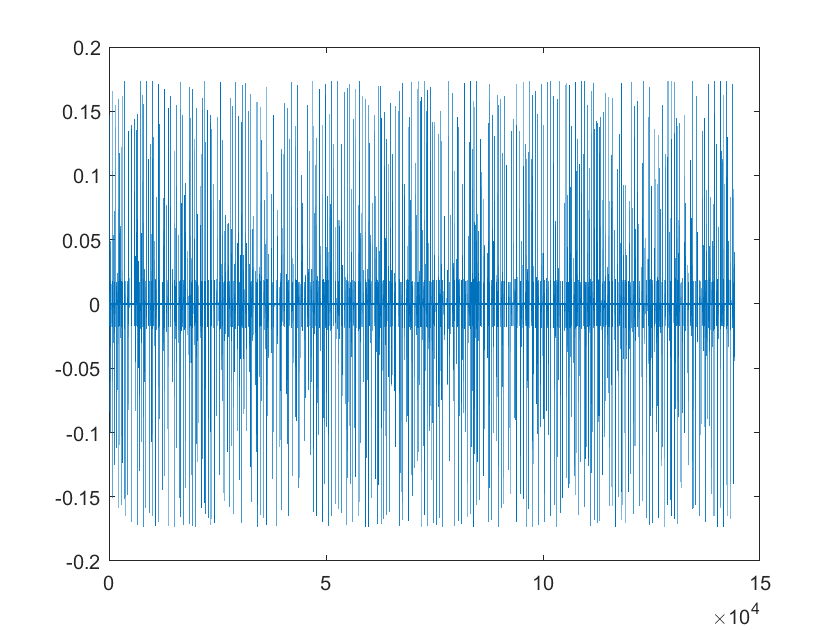

plot(imag(y_complex))

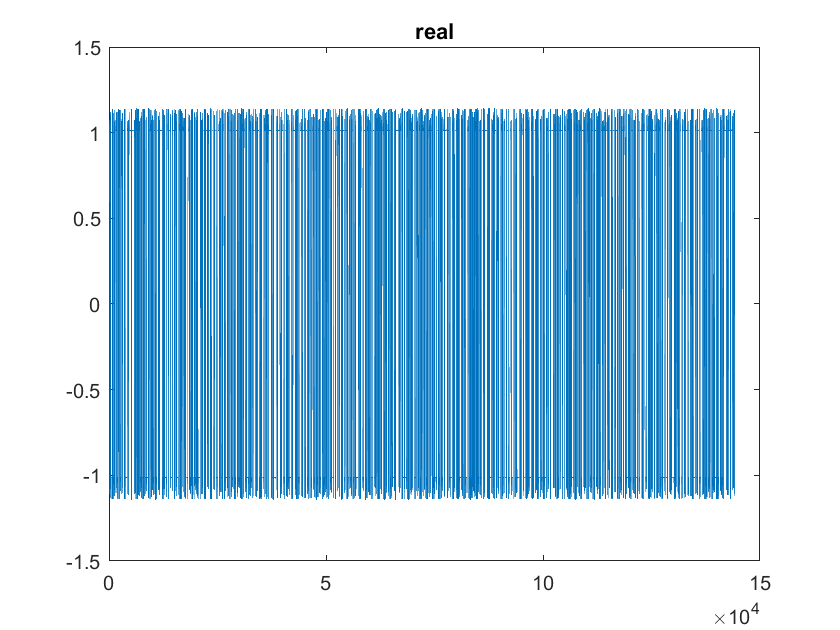


% normalize received signal
y_complex = transpose(y_complex);
y_mag = rms(y_complex);
y_complex = y_complex ./ y_mag;
y_size = size(y_complex);

% initialize all variables
phi = zeros(y_size(1),1);
x_prime = zeros(y_size(1),1);
e = zeros(y_size(1), 1);
d = zeros(y_size(1),1);
k = 1;
%setting the value for alpha and beta
beta = 0.1;
alpha = 0.01;

% loop through k and minize error
while k < y_size(1)
    x_prime(k) = y_complex(k) * exp(j*phi(k));
    e(k) = -real(x_prime(k)) * imag(x_prime(k));
    d(k) = beta * e(k) + alpha * sum(e(1:k));
    phi(k+1) = phi(k) + d(k);
    while phi(k+1) < -pi
        phi(k+1) = phi(k+1) + 2*pi;
    end
    while phi(k+1) > pi
        phi(k+1) = phi(k+1) - 2*pi;
    end
    k = k + 1;
end
plot(real(x_prime))
title('real')

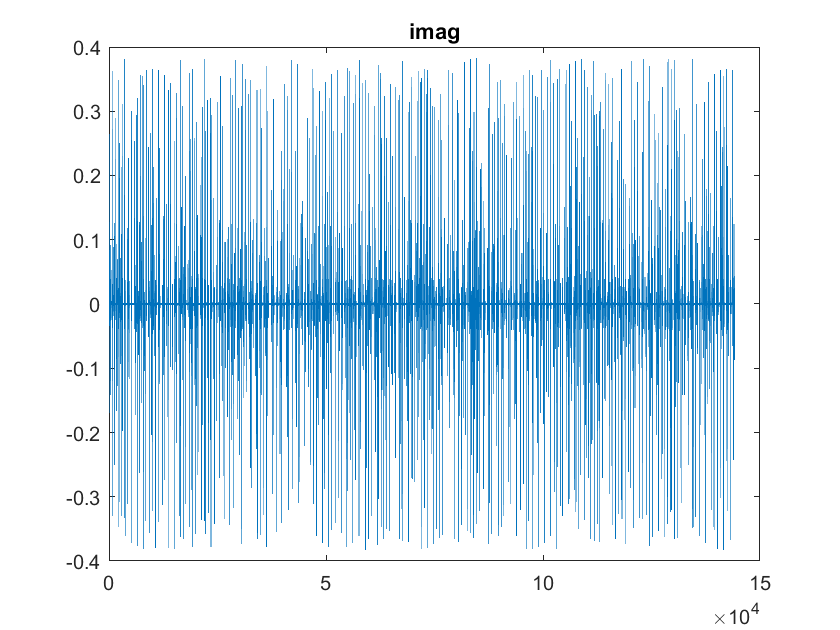

plot(imag(x_prime))
title('imag')


x_res = downsample(real(x_prime), 100);
% converting to 1 and 0
for i=1:size(x_res)
    if x_res(i) > 0
        x_res(i) = 1;
    end
    if x_res(i) < 0
        x_res(i) = 0;
    end
end

% break down long string into individual character
full_str = sprintf('%d',x_res');
% diff is added here to correct for possible offset
diff = 1;
full_str = full_str(1+diff:1435+diff);
str_size = idivide(int16(strlength(full_str)),int16(7));
ascii_list = strings(str_size, 1);
for i = 0:str_size-1
    ascii_list(i+1) = full_str(i*7+1:(i+1)*7);
end
result = "";
for i = 1:str_size
    result = append(result, char(bin2dec(ascii_list(i))));
end
result

result = "hKlYoAw_rYd@mIgKr@oAf@s^!daM!]{ckCc\,@[QgPg^!HoKr@o_t@wKad!OlCsgegScQe\`gMksqEh@{Ai\cByeu^v@omp@k]qXcYc^uAuSo\!Sr@iCsIWScWyAif`Qaapr`ghJ@Ss!A!sFigcbj@k^oQmMcbk^g1kGiIl@kg!gw`sSsKdAcr!-iGkssAcCrKed`GH_Ig"